# Parameter estimation for auxiliary model 1

## Definition of the model

clear;clc;close all
ParNames =  {'\gamma_1','\gamma_2','\gamma_3','\gamma_4','\alpha_1','\alpha_2',...
    '\alpha_3','\alpha_4'};
VarNames = {'D_{11}','D_{12}','D_{13}','D_{14}','D_{22}','D_{23}','D_{24}',...
    'D_{33}','D_{34}','D_{44}','R_1','R_2','R_3','R_4','X_1','X_2','X_3','X_4'};
OutNames = {'D_{11}','D_{12}','D_{13}','D_{14}','D_{22}','D_{23}','D_{24}',...
    'D_{33}','D_{34}','D_{44}','R_1','R_2','R_3','R_4','X_1','X_2','X_3','X_4'};

FullNames = [VarNames,ParNames];
initPob=1e5;
Range1 = zeros(18,2);
Range1([1,5,8,10],:)=1e5;

Range2 = [zeros(8,1),ones(8,1)];
Range2(5:7,2)=[0.6398 0.6532 0.5479]';%Topes de los alfas dado el modelo auxiliar de estimación 2

RangeT = [Range1; Range2];

  T = gsua_dataprep("estimModel", RangeT, 'domain', [0 24], 'names',...
        FullNames, 'out_names', OutNames);

Setting environment to work with user-defined function


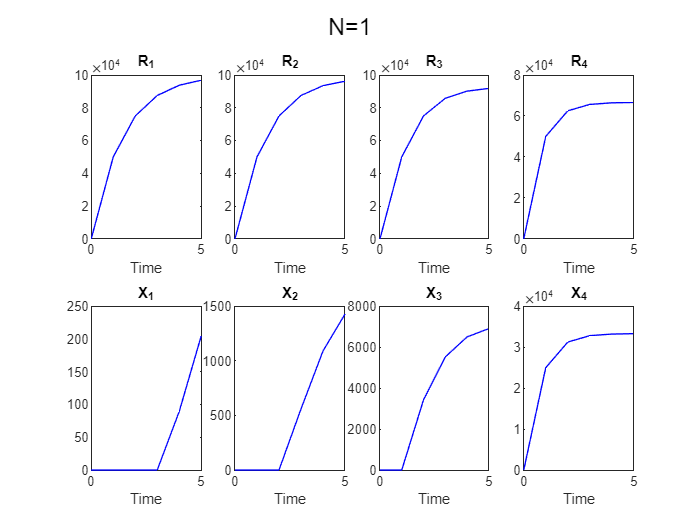

T.Properties.CustomProperties.output=11:18;
y=gsua_eval(T.Nominal,T,0:5);

## Parameter estimation

### Worst case

supervivencias1=[0.707 0.662 0.576 0.376];
R1=initPob*supervivencias1;
X1=initPob*(1-supervivencias1);
fcurve1=[R1 X1]'*linspace(0.99,1,12)

fcurve1 = 1.0e+04 *

    6.9993    7.0057    7.0122    7.0186    7.0250    7.0314    7.0379    7.0443    7.0507    7.0571    7.0636    7.0700
    6.5538    6.5598    6.5658    6.5719    6.5779    6.5839    6.5899    6.5959    6.6019    6.6080    6.6140    6.6200
    5.7024    5.7076    5.7129    5.7181    5.7233    5.7286    5.7338    5.7391    5.7443    5.7495    5.7548    5.7600
    3.7224    3.7258    3.7292    3.7327    3.7361    3.7395    3.7429    3.7463    3.7497    3.7532    3.7566    3.7600
    2.9007    2.9034    2.9060    2.9087    2.9114    2.9140    2.9167    2.9193    2.9220    2.9247    2.9273    2.9300
    3.3462    3.3493    3.3523    3.3554    3.3585    3.3616    3.3646    3.3677    3.3708    3.3739    3.3769    3.3800
    4.1976    4.2015    4.2053    4.2092    4.2130    4.2169    4.2207    4.2246    4.2284    4.2323    4.2361    4.2400
    6.1776    6.1833    6.1889    6.1946    6.2003    6.2060    6.2116    6.2173    6.2230    6.2287    6.2343    6.2400


Generating a valid matrix for estimations
Estimation 1

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Estimation 2

Local minimum possible. Constraints satisfied.

fmincon stopped 

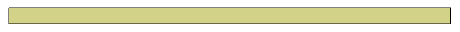

Estimation 1000

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Tp1 = 8×3 table
                  Range      Nominal     Estfmincon  
                _________    _______    _____________

    \gamma_1    0       1       0.5     1×1000 double
    \gamma_2    0       1       0.5     1×1000 double
    \gamma_3    0       1       0.5     1×1000 double
    \gamma_4    0       1       0.5     1×1000 double
    \alpha_1    0     0.7      0.35     1×1000 double
    \alpha_2    0    0.65     0.325     1×1000 double
    \alpha_3    0    0.65     0.325     1×1000 double
    \alpha_4    0       1       0.5     1×1000 double


Tp1=gsua_pe(T,13:24,fcurve1,'solver','fmincon','N',5e2)

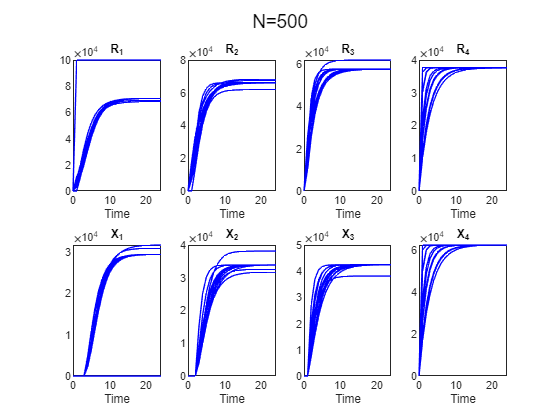

figure(1)
clf
gsua_eval(Tp1.Estfmincon,T);

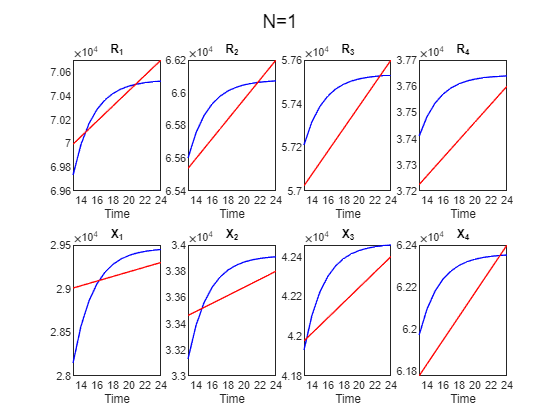

figure(2)
clf
gsua_eval(Tp1.Estfmincon(:,1),T,13:24,fcurve1);

### Intermediate case

supervivencias2=[0.787 0.762 0.678 0.562];
R2=initPob*supervivencias2;
X2=initPob*(1-supervivencias2);
fcurve2=[R2 X2]'*linspace(0.99,1,12)

fcurve2 = 1.0e+04 *

    7.7913    7.7985    7.8056    7.8128    7.8199    7.8271    7.8342    7.8414    7.8485    7.8557    7.8628    7.8700
    7.5438    7.5507    7.5577    7.5646    7.5715    7.5784    7.5854    7.5923    7.5992    7.6061    7.6131    7.6200
    6.7122    6.7184    6.7245    6.7307    6.7369    6.7430    6.7492    6.7553    6.7615    6.7677    6.7738    6.7800
    5.5638    5.5689    5.5740    5.5791    5.5842    5.5893    5.5945    5.5996    5.6047    5.6098    5.6149    5.6200
    2.1087    2.1106    2.1126    2.1145    2.1164    2.1184    2.1203    2.1223    2.1242    2.1261    2.1281    2.1300
    2.3562    2.3584    2.3605    2.3627    2.3649    2.3670    2.3692    2.3713    2.3735    2.3757    2.3778    2.3800
    3.1878    3.1907    3.1937    3.1966    3.1995    3.2024    3.2054    3.2083    3.2112    3.2141    3.2171    3.2200
    4.3362    4.3402    4.3442    4.3481    4.3521    4.3561    4.3601    4.3641    4.3681    4.3720    4.3760    4.3800


Generating a valid matrix for estimations
Estimation 1

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Estimation 2

Local minimum possible. Constraints satisfied.

fmincon stopped 

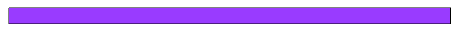

Estimation 1000

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Tp2 = 8×3 table
                  Range      Nominal     Estfmincon  
                _________    _______    _____________

    \gamma_1    0       1       0.5     1×1000 double
    \gamma_2    0       1       0.5     1×1000 double
    \gamma_3    0       1       0.5     1×1000 double
    \gamma_4    0       1       0.5     1×1000 double
    \alpha_1    0     0.7      0.35     1×1000 double
    \alpha_2    0    0.65     0.325     1×1000 double
    \alpha_3    0    0.65     0.325     1×1000 double
    \alpha_4    0       1       0.5     1×1000 double


Tp2=gsua_pe(T,13:24,fcurve2,'solver','fmincon','N',5e2)

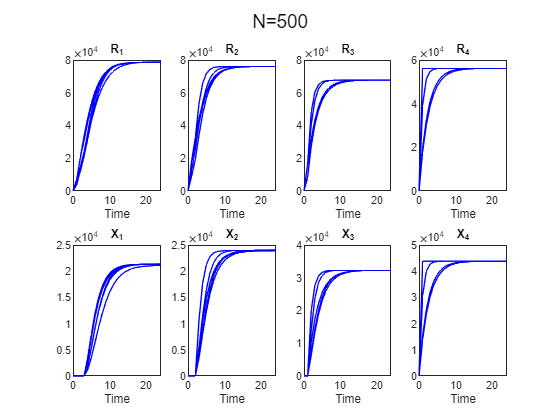

figure(3)
clf
gsua_eval(Tp2.Estfmincon,T);

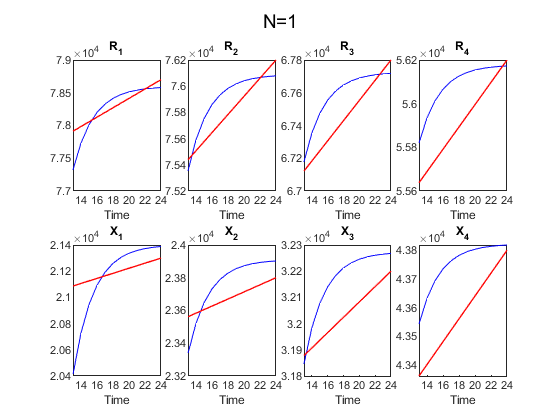

figure(4)
clf
gsua_eval(Tp2.Estfmincon(:,1),T,13:24,fcurve2);

### Best case

supervivencias3=[0.867 0.861 0.78 0.747];
R3=initPob*supervivencias3;
X3=initPob*(1-supervivencias3);
fcurve3=[R3 X3]'*linspace(0.99,1,12)

fcurve3 = 1.0e+04 *

    8.5833    8.5912    8.5991    8.6069    8.6148    8.6227    8.6306    8.6385    8.6464    8.6542    8.6621    8.6700
    8.5239    8.5317    8.5396    8.5474    8.5552    8.5630    8.5709    8.5787    8.5865    8.5943    8.6022    8.6100
    7.7220    7.7291    7.7362    7.7433    7.7504    7.7575    7.7645    7.7716    7.7787    7.7858    7.7929    7.8000
    7.3953    7.4021    7.4089    7.4157    7.4225    7.4293    7.4360    7.4428    7.4496    7.4564    7.4632    7.4700
    1.3167    1.3179    1.3191    1.3203    1.3215    1.3227    1.3240    1.3252    1.3264    1.3276    1.3288    1.3300
    1.3761    1.3774    1.3786    1.3799    1.3812    1.3824    1.3837    1.3849    1.3862    1.3875    1.3887    1.3900
    2.1780    2.1800    2.1820    2.1840    2.1860    2.1880    2.1900    2.1920    2.1940    2.1960    2.1980    2.2000
    2.5047    2.5070    2.5093    2.5116    2.5139    2.5162    2.5185    2.5208    2.5231    2.5254    2.5277    2.5300


Generating a valid matrix for estimations
Estimation 1

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Estimation 2

Local minimum possible. Constraints satisfied.

fmincon stopped 

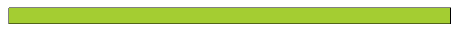

Estimation 1000

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Tp3 = 8×3 table
                  Range      Nominal     Estfmincon  
                _________    _______    _____________

    \gamma_1    0       1       0.5     1×1000 double
    \gamma_2    0       1       0.5     1×1000 double
    \gamma_3    0       1       0.5     1×1000 double
    \gamma_4    0       1       0.5     1×1000 double
    \alpha_1    0     0.7      0.35     1×1000 double
    \alpha_2    0    0.65     0.325     1×1000 double
    \alpha_3    0    0.65     0.325     1×1000 double
    \alpha_4    0       1       0.5     1×1000 double


Tp3=gsua_pe(T,13:24,fcurve3,'solver','fmincon','N',5e2)

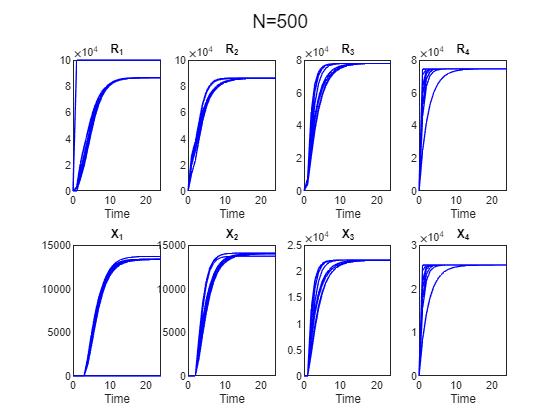

figure(5)
clf
gsua_eval(Tp3.Estfmincon,T);

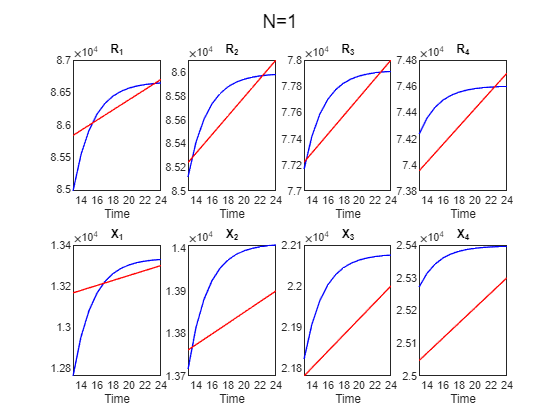

figure(6)
clf
gsua_eval(Tp3.Estfmincon(:,1),T,13:24,fcurve3);

estims=[Tp1.Estfmincon,Tp2.Estfmincon,Tp3.Estfmincon]

estims =     0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882    0.0882
    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413    0.1413

save('Estim_auxModel3','estims');

## Assessment of estimations

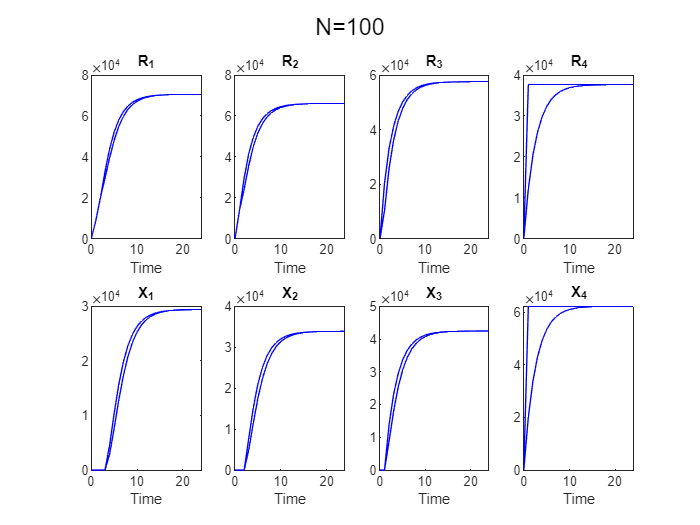

load Estim_auxModel3.mat
figure(7)
clf
gsua_eval(estims(:,1:100),T);

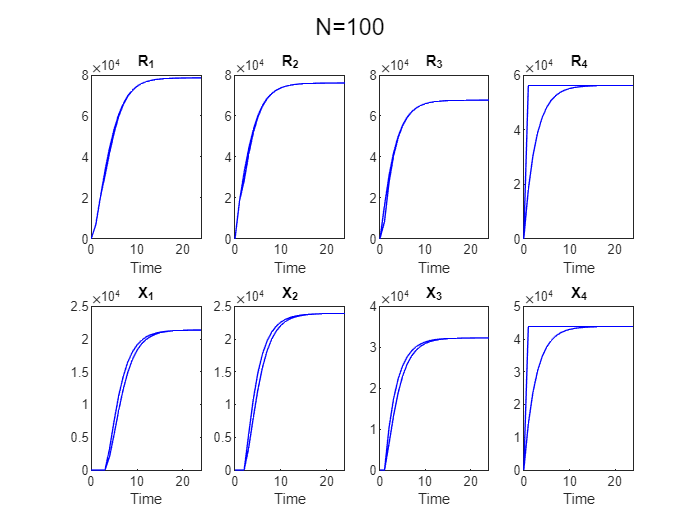

figure(8)
clf
gsua_eval(estims(:,501:600),T);

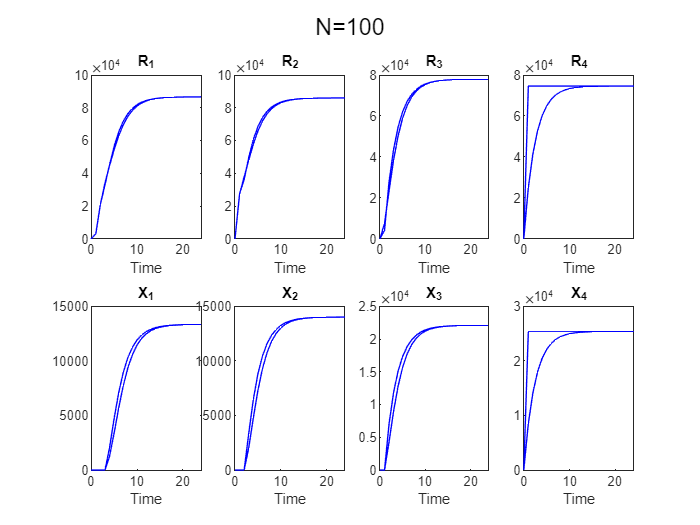

figure(9)
clf
gsua_eval(estims(:,1001:1100),T);

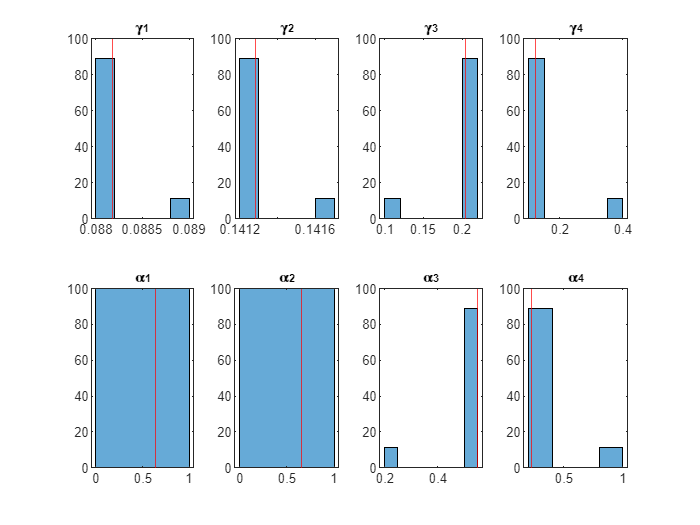

figure(10)
clf
for i=1:8
    subplot(2,4,i)
    histogram(estims(i,1:100))
    xline(estims(i,1),'r')
    title(T.Properties.RowNames{i})
end

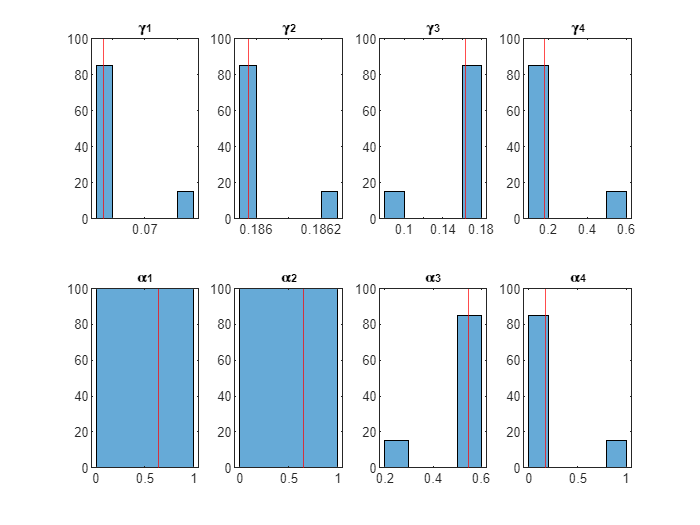

figure(11)
clf
for i=1:8
    subplot(2,4,i)
    histogram(estims(i,501:600))
    xline(estims(i,501),'r')
    title(T.Properties.RowNames{i})
end

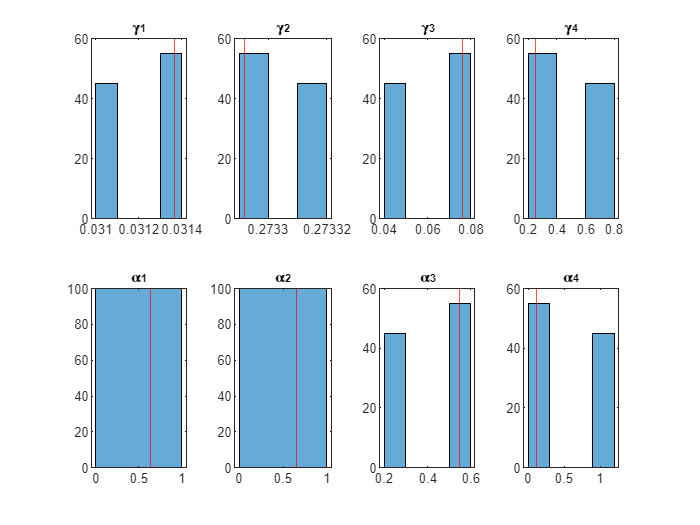

figure(12)
clf
for i=1:8
    subplot(2,4,i)
    histogram(estims(i,1001:1100))
    xline(estims(i,1001),'r')
    title(T.Properties.RowNames{i})
end

#### Parameters for worst case

Better estimations converged to the same minimum

Tp1(:,"Estfmincon")

ans = 8×1 table
                 Estfmincon 
                ____________

    \gamma_1    1×500 double
    \gamma_2    1×500 double
    \gamma_3    1×500 double
    \gamma_4    1×500 double
    \alpha_1    1×500 double
    \alpha_2    1×500 double
    \alpha_3    1×500 double
    \alpha_4    1×500 double


#### Parameters for intermediate case

Better estimations converged to the same minimum

Tp2(:,"Estfmincon")

ans = 8×1 table
                 Estfmincon 
                ____________

    \gamma_1    1×500 double
    \gamma_2    1×500 double
    \gamma_3    1×500 double
    \gamma_4    1×500 double
    \alpha_1    1×500 double
    \alpha_2    1×500 double
    \alpha_3    1×500 double
    \alpha_4    1×500 double


#### Parameters for better case

Better estimations converged to the same minimum

Tp3(:,"Estfmincon")

ans = 8×1 table
                 Estfmincon 
                ____________

    \gamma_1    1×500 double
    \gamma_2    1×500 double
    \gamma_3    1×500 double
    \gamma_4    1×500 double
    \alpha_1    1×500 double
    \alpha_2    1×500 double
    \alpha_3    1×500 double
    \alpha_4    1×500 double
